# Dataset generation for identifying a transfer function model of T200 thruster from Blue Robotics

H. Garnier - 4/03/2022

This file imports raw data and generates two datasets collected from a sine and square chirp experiment applied to the thruster.

The measured output is the generated force (in lb).

## First load the data

load thruster_data.mat

Two datasets are available collected from a sine and sine chirp experiment applied to the thruster.

**y_sine**,  contains 15001 sampled measurements of force generated (in lb) sine chirp experiment

**u_sine** contains 15001 the sine chirp swept-frequency input data samples applied to the thruster

The sampling interval is **Ts**=0.002 seconds.

**data_sine** contains the data from the sine chirp experiment gathered in an IDDATA object

**y_square**,  contains 15001 sampled measurements of force generated (in lb) for the square chirp experiment

**u_square** contains 15001 the square chirp swept-frequency input data samples applied to the thruster

The sampling interval is **Ts**=0.002 seconds.

**data_square** contains the data from the square chirp experiment gathered in an IDDATA object

## Time-domain analysis of the sine chirp data

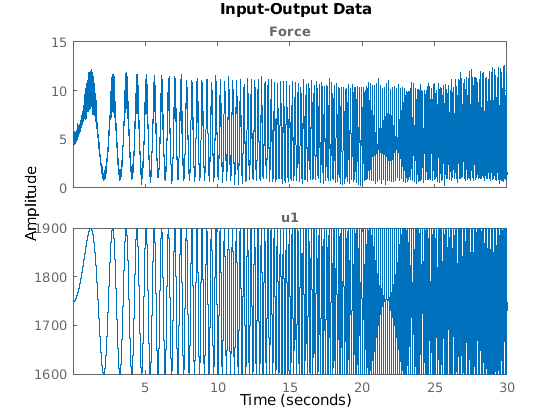

N=length(u_sine);
t=0:Ts:(N-1)*Ts;
data_sine.OutputName = 'Force';
data_sine.OutputUnit = 'lb';
data_sine.TimeUnit   = 'seconds';
idplot(data_sine)

saveFigure(gcf, 'figures/chirp-data')

##  Time-domain analysis of the square chirp data

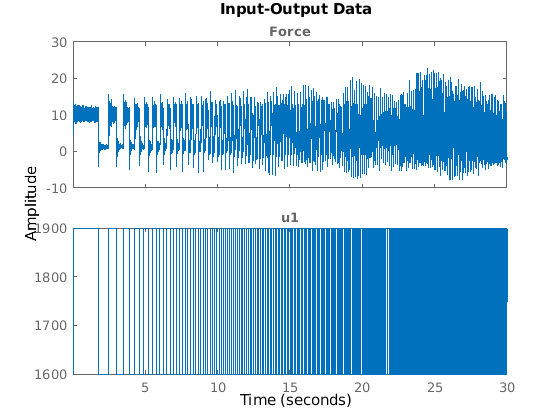

data_square.OutputName = 'Force';
data_square.OutputUnit = 'lb';
data_square.TimeUnit   = 'seconds';

figure
idplot(data_square)
saveFigure(gcf, 'figures/square-chirp-data')

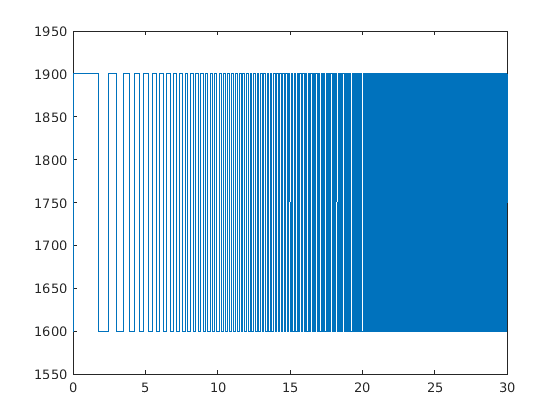

% determine highest frequency of input signal
% visual inspection 
plot(t, u_square);
ylim([1550 1950])

% same last period lenght for the square chirp signal
u_sine_lastPeriodLength = 29.975 - 29.875;
u_sine_highestFrequency = 1 / u_sine_lastPeriodLength

u_sine_highestFrequency = 10.0000